This script is to analyze the FLP data from running vs resting experiment of mouse 1521, which has ACh sensor expressed in dorsal hippocampus. The purpose of the experiment is:

- For this mouse particularly, compare intensity and lifetime in reflecting running vs resting state from different acqns of different photon count (laser power).

- Repeat the running vs resting acqns three times, with exactly the same settings, to see how reliable the readout is.

cd('/Volumes/PcSSDA/AChMut/20220208_112_8_AChMut_RvR_001')
ExperimentName='20220208_112_8_AChMut_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];
    

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end


i=1;
filename=[analysis_name,num2str(i),'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[analysis_name,'FLP.csv']

FLP_all_csv = '20220208_112_8_AChMut_RvR_001_analysis_FLP.csv'

writetable(FLP_all, FLP_all_csv)

This part is to read the speed file and plot the speed and FLP data together.

timestamp_file='20220208_112_8_AChMut_RvR_001_timestamp0.csv';

speed_file='20220208_112_8_AChMut_RvR_001_speedonly.csv';

str=readtable(timestamp_file,'ReadVariableNames',false,'Delimiter',' ');
str=table2cell(str);
dts=datetime(str,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SXXXXXX','TimeZone','America/Chicago');
dts_norm=dts-dts(1);
time_from_bonsai=seconds(dts_norm);


speed=readtable(speed_file,'ReadVariableNames',true);
speed=table2array(speed);
speed(end)=[];


speed_time_for_FLP=[];

for i=1:size(time,1)
    
    
        if time(i)<=3600
           speed_time_for_FLP(i)=find(histc(time(i),[time_from_bonsai; 3600])==1);
        else
            speed_time_for_FLP(i)=size(time_from_bonsai,1);
        end
end


speed_for_FLP=speed(speed_time_for_FLP);


speed_for_FLP=transpose(speed_for_FLP);


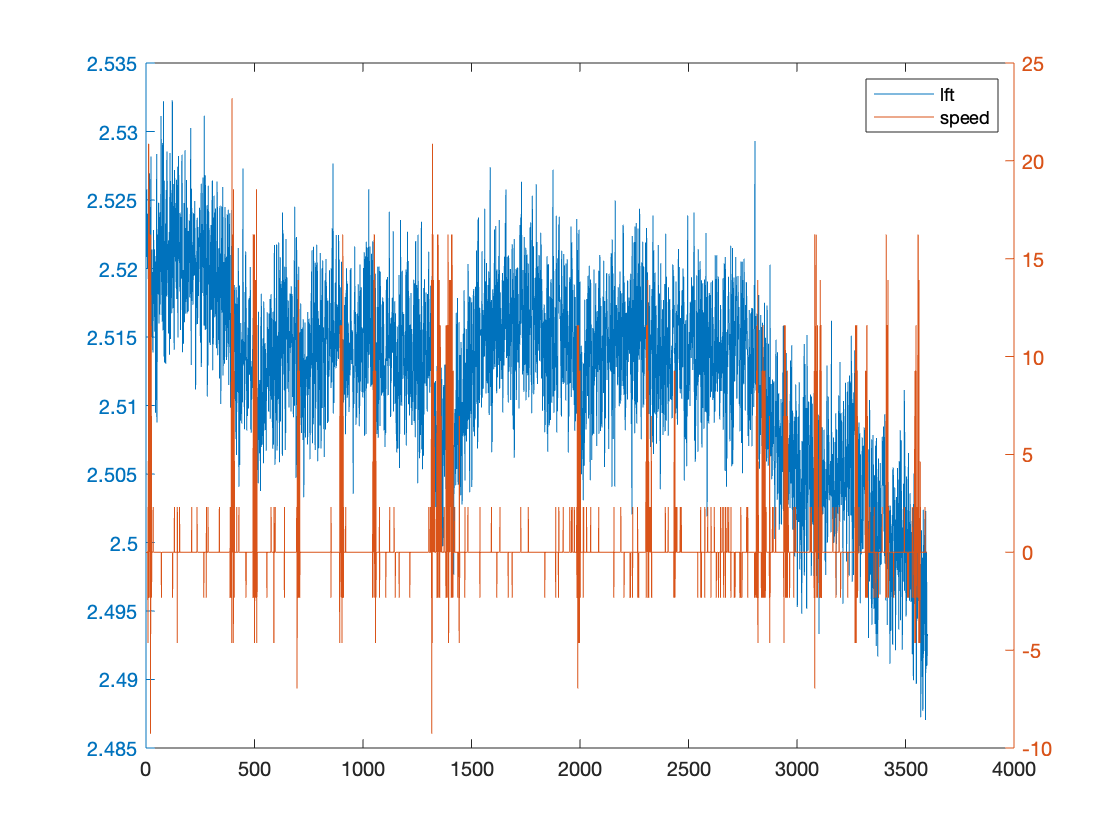

figure
yyaxis left
plot(time,tau_empTrunc);
yyaxis right
plot(time_from_bonsai,speed)
legend('lft', 'speed')

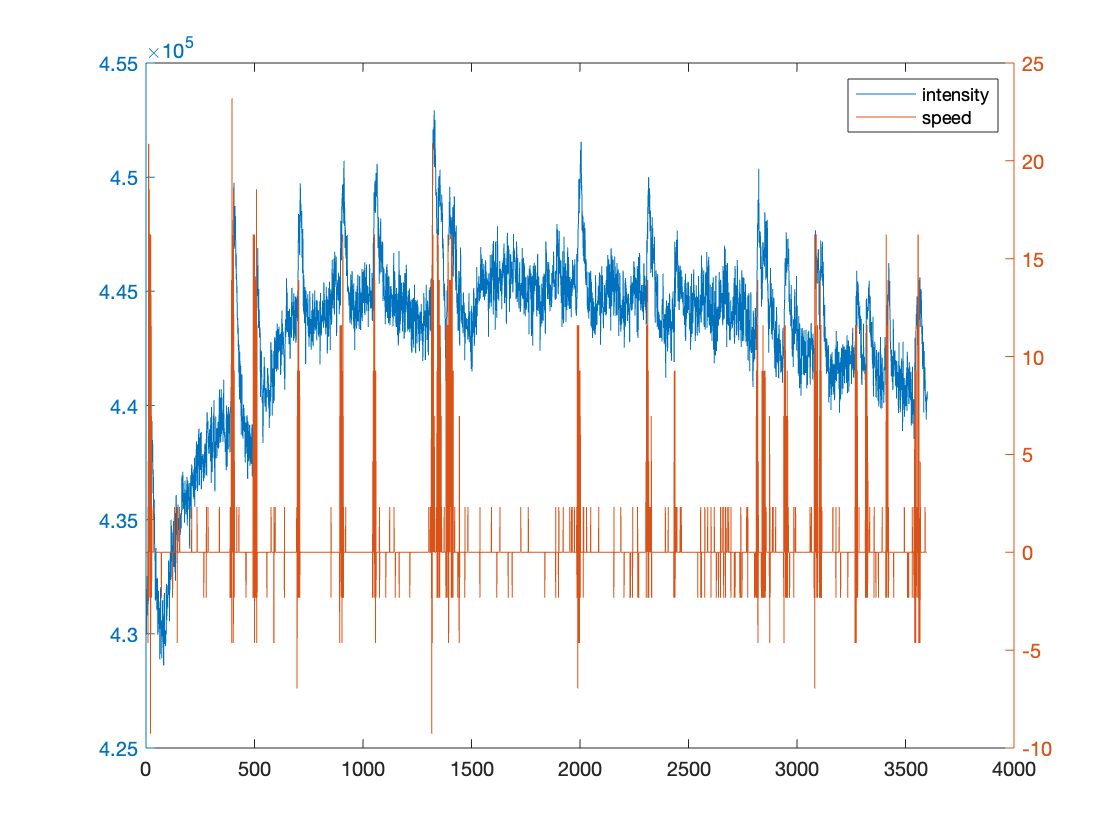


figure
yyaxis left
plot(time,photoncount);
yyaxis right
plot(time_from_bonsai,speed)
legend('intensity','speed')

This part is to write the csv files.

for i=1:number_of_acq
    filename=[analysis_name,num2str(i),'.mat'];
    load(filename)
    
    time_csv=[filename,'_time.csv'];
    intensity_csv=[filename,'_intensity.csv'];
    lft_fit_csv=[filename,'_tau_fitting.csv'];
    lft_emp_csv=[filename,'_tau_emp.csv'];
    
    csvwrite(time_csv,time);
    csvwrite(intensity_csv,photoncount);
    csvwrite(lft_fit_csv,tau_avg);
    csvwrite(lft_emp_csv,tau_empTrunc);
end

This part is to read the speed information.

First I need to set up a csv file that only contains the speed information (removing the column of timestamp, I had tome tenical issue with reading the file with two columns (timestamp and speed),). Then the speed and time information will be read from separate csv files respectively.

for i=1:number_of_acq
    
    timestamp_file=[ExperimentName,'_timestamp',num2str(i-1),'.csv'];
    speed_file=[ExperimentName,'_speed',num2str(i-1),'only.csv'];
    
    str=readtable(timestamp_file,'ReadVariableNames',false,'Delimiter',' ');
    str=table2cell(str);
    dts=datetime(str,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SXXXXXX','TimeZone','America/Chicago');
    dts_norm=dts-dts(1);
    time_from_bonsai=seconds(dts_norm);
    eval(['timestamp',num2str(i),'=time_from_bonsai;'])
    
    speed=readtable(speed_file,'ReadVariableNames',true);
    speed=table2array(speed);
    speed(end)=[];
    eval(['speed',num2str(i),'=speed;'])
    
    
end

save('analysis.mat')

Saving wave object  ...
Saving wave object  ...
Saving wave object  ...
